# Capacitors: fluid analogy

[⇦ Main Menu](matlab:open('..\MainMenu.mlx'))

In this script, we will use a fluid analogy to help readers gain a more intuitive understanding of a capacitor.

[image: double_actuator.svg]

Image a hydraulic piston

- In green, you have the hydraulic piston casing.

- In red is the piston itself.

- We can pump fluid in and out of cavities A and B, but they are not directly connected inside the system.

 **Exercise 9.** What would happen if we pump fluid into cavity A?

switch "Select"
    case "Select"
        warning("Please select a valid answer.")
    case "Right"
        disp("Right! Pumping fluid into cavity A would lead to a displacement of the piston to the right.")
    case "Left"
        warning("Pumping fluid into cavity A would increase the pressure inside Cavity A and impose a force on the piston. Which way will the piston move then?")
end

 
figure
[Img,~,~] = imread(fullfile("Images","HintCapacitorEx9.png"));
imshow(Img)
title("Cavity A is colored in orange")

Now that you are familiar with hydraulic pistons, we prepared a Simscape model to compare them to capacitors.

  **Try. **Open the model and explore the different blocks that it is built out of.

 
open_system(fullfile("Models","FluidAnalogy.slx"));

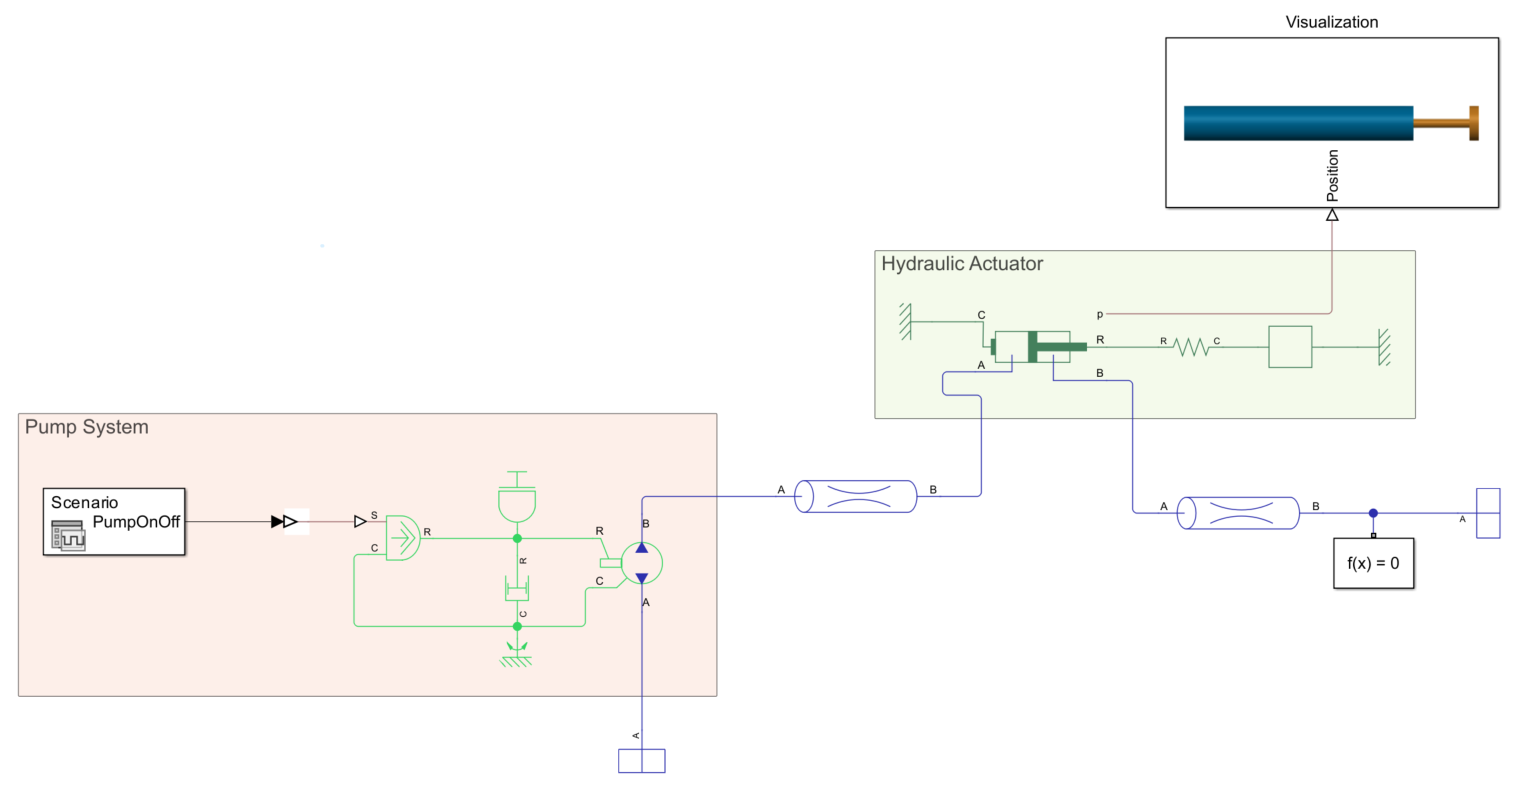

- The red region represents the pump system; it is the direct equivalent of the power supply in our RC circuit.

- The hydraulic actuator is equivalent to the capacitor, composed of a hydraulic piston and a mass-spring system.

- A visualization subsystem is attached to the simulation to visualize the piston movement.

- The pipes connecting the pump and actuator are equivalent to the resistor in the RC circuit.

The simulation scenario starts with all the components at rest. At `t= 5` seconds, the pump turns on, increasing the pressure in cavity A, compressing the spring, and making the mass move towards the right.

 **Exercise 10. **At `t = 10` seconds, the pump turns off; what should we expect the system to do?

switch "Select"
    case "Select"
        warning("Please select a valid answer.")
    case "Nothing"
        warning("If there were no spring in the system this would be correct, but the spring stores energy that will be returned to the piston when the pump stops.")
    case "Right"
        warning("The system would not keep moving towards the right, try again.")
    case "Left"
        disp("Right! We can expect the spring to bring the system back to its equilibrium position.")
end

  **Try. **Let's try it! After reopening the model and running the simulation, you should be able to visualize the piston moving in 3D.

 
open_system(fullfile("Models","FluidAnalogy.slx"));

In this fluid analogy, you can consider the following:

- The pressure is equivalent to the voltage imposed by the power supply

- The current is equivalent to the mass flow in the system

- The capacitor is equivalent to the action of the spring on the piston

Click the video above to view the result of the simulation

 **Bonus. **The system has a physical limit to how much it can extend. Therefore, there is a limit to how much energy it can store. A capacitor will store more and more energy as more and more voltage is applied to it. Could it potentially store an infinite amount of energy?... No, because the material used to separate the two charged plates, whether air or dielectric, has a limit above which it will start conducting electricity, short-circuiting the system and often exploding. This is why capacitors are rated with a maximum voltage limit. In a way, it would be equivalent to supplying infinite pressure to our hydraulic piston; at some point, the material composing the cylinder would fail, and the system would explode.

[⇦ Return to the main menu](matlab:open('..\MainMenu.mlx'))